# Analyzing the OVT 3-capture sensor

We simulate an HDR tunnel scene using a split-pixel sensor, following the Omnivision paper by 

    J. Solhusvik, T. Willassen, S. Mikkelsen, M. Wilhelmsen, S. Manabe, D. Mao, Z. He, K. Mabuchi, and T. Hasegawa

    “A 1280x960 2.8μm2 HDR CIS with DCG and split-pixel combined,” 

    in International Image Sensors Workshop, 2019.

For the split pixel, we compare the pure LPD-LCG rendering with the rendering we get when we use the LPD-HCG and SPD-LCG.

We write out the sensor images, and we also compare the noise along a couple of lines by plotting the response and plotting the simulation noise free.

We also calculate the variance explained (R squared) of the noise free and the noisy, to illustrate that the split pixel design does better.

## Check for the tunnel scene

If that scene is not already in the data/oiTunnel.mat location, we download it from the Stanford Data Repository using the ISETCam ieWebGet() method.

ieInit;

oiFile = fullfile(isethdrsensorRootPath,'data','oiTunnel.mat');
if ~exist(oiFile,"file")
    % download the file from SDR
    ieWebGet('resourcetype','isethdrsensor',...
        'resource name','data/oiTunnel.mat',...
        'download dir',isethdrsensorRootPath);
end
load(oiFile,'oiInput');

## Set a long exposure time parameter

% Long exposure forces saturation of the LPD
expTime   = 120e-3;   
satLevel  = .99;

## Simulate the Omnivision (OVT) Split pixel technology

We create an array of three sensors that match the large photodetector with high and low gain and the small photodetector. 

pixelSize = [3 3]*1e-6;
sensorSize = [1082 1926];

arrayType = 'ovt'; 
sensorArray = sensorCreateArray('array type',arrayType,...
    'pixel size same fill factor',pixelSize,...
    'exp time',expTime, ...
    'quantizationmethod','analog', ...
    'size',sensorSize);

## Compute the 3-captures and also return the combined data

sensorSplit has the combined data.  sensorArraySplit has each of the three captures.

[sensorSplit,sensorArraySplit] = sensorComputeArray(sensorArray,oiInput,...
    'method','saturated', ...
     'saturated',satLevel);

## Image process the sensor data.

The sensorArraySplit(1) shows the large photodetector with low conversion gain.  The sensorArraySplit(3) shows the small photodetector.

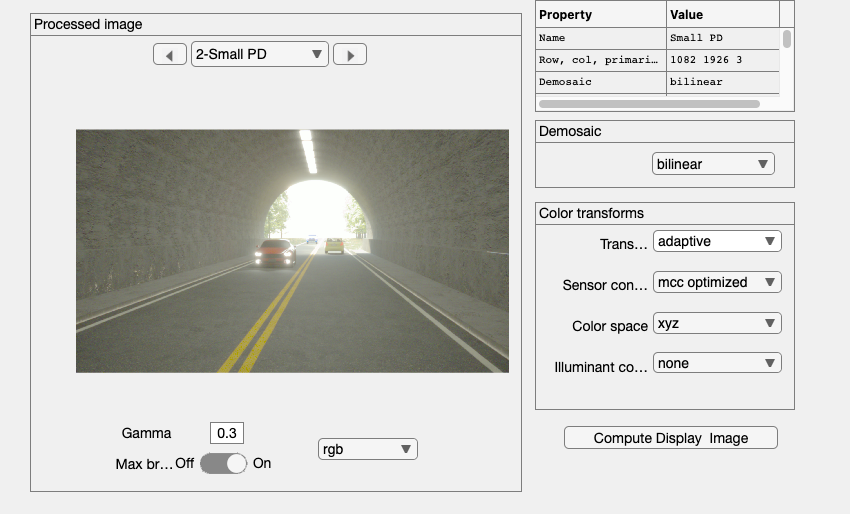

ipLPD = ipCreate;
ipLPD = ipCompute(ipLPD,sensorArraySplit(1),'hdr white',true);
ipLPD = ipSet(ipLPD,'name','Large PD');
ipWindow(ipLPD,'render flag','rgb','gamma',0.3); drawnow;

ipSPD = ipCreate;
ipSPD = ipCompute(ipSPD,sensorArraySplit(3),'hdr white',true);
ipSPD = ipSet(ipSPD,'name','Small PD');
ipWindow(ipSPD,'render flag','rgb','gamma',0.3); drawnow;

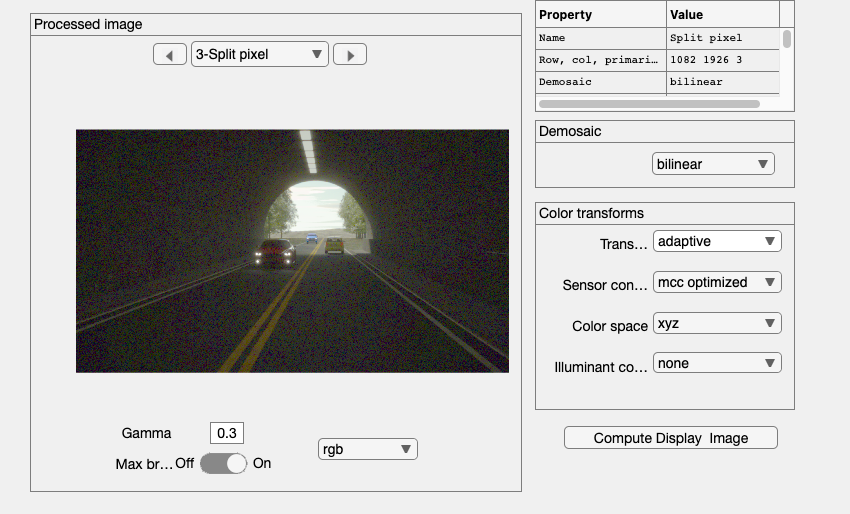

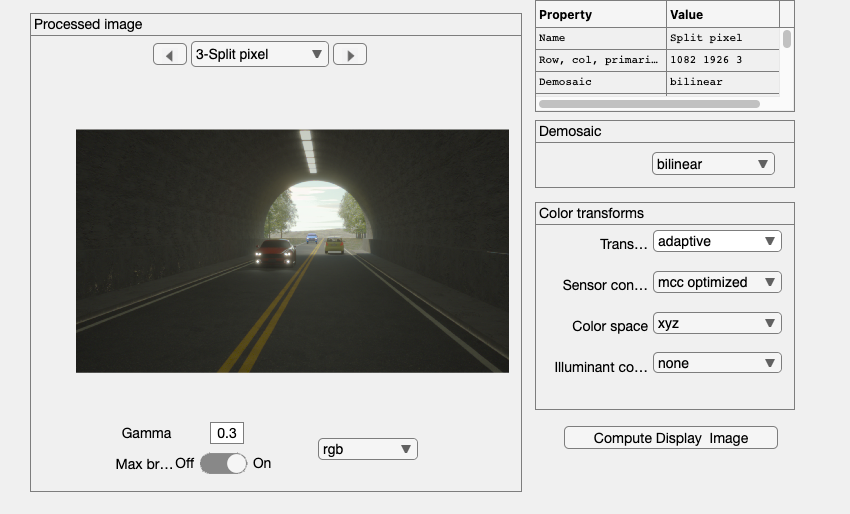


ipSplit = ipCreate;
ipSplit = ipCompute(ipSplit,sensorSplit,'hdr white',true);
ipSplit = ipSet(ipSplit,'name','Split pixel');
ipWindow(ipSplit,'render flag','rgb','gamma',0.3); drawnow;

To save out the images, you can use code like this:

## Show the improved spatial representation near the headlights

After running this block, if you would like to save the plot as a PDF, you can use this code

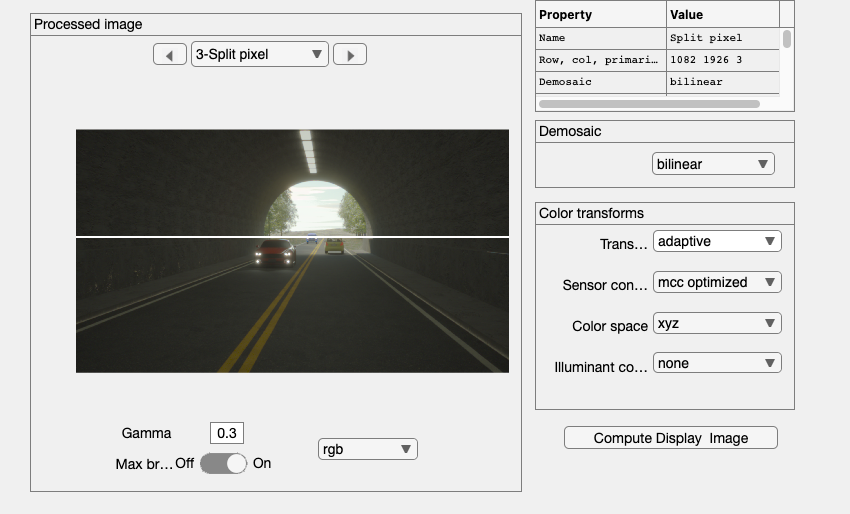

lineNumber = 479;
uSplit = ipPlot(ipSplit,'horizontal line luminance',[1 lineNumber],'no figure');
uLPD   = ipPlot(ipLPD,'horizontal line luminance',[1 lineNumber],'no figure');

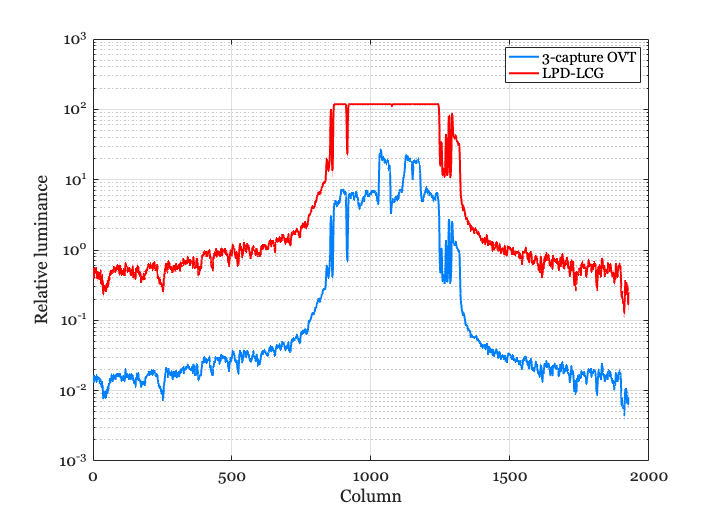


ieNewGraphWin;
p = plot(uSplit.pos,uSplit.data,'Color',[0 0.5 1],'LineWidth',2); hold on;
plot(uLPD.pos,uLPD.data,'r-','LineWidth',2);

legend({'3-capture OVT','LPD-LCG'}); grid on; 
xlabel('Column'); ylabel('Relative luminance');
set(gca,'yscale','log'); grid on